% Load data
clear all;
format long
load("raw.mat");

% Part 1
size(onunivcol16)

ans =        23319           3


mean(onunivcol16.Salary)

ans =      1.418597888288528e+05

std(onunivcol16.Salary)

ans =      4.143585115136906e+04

% Part 2
pop = height(onunivcol16);
rand_sample_idx = zeros(100, 3);
for i = 1:3
    pm = randperm(pop);
    rand_sample_idx(:, i) = pm(1:100);
    selected_sample = onunivcol16.Salary(rand_sample_idx(:,i), 1);
    onunivcol16S2(:, i) = selected_sample;
end

onunivcol16S2 = 	1.0e+06 *

   0.110491600000000                 NaN                 NaN   0.100553400000000   0.157001700000000   0.123197500000000   0.110309300000000   0.116828100000000   0.121197300000000   0.149409200000000   0.167003300000000   0.103768800000000   0.188424800000000   0.105559100000000   0.105154600000000   0.104788000000000   0.125072600000000   0.105559100000000   0.126482600000000   0.152822200000000   0.115483300000000   0.130381700000000   0.198352000000000   0.108572700000000   0.108028200000000   0.209449300000000   0.114777000000000   0.107521500000000   0.131289000000000   0.129525500000000   0.254999700000000   0.103821300000000   0.169721500000000   0.284903500000000   0.178111500000000   0.114654100000000   0.124836500000000   0.107675400000000   0.138382900000000   0.109881800000000   0.162328300000000   0.127500000000000   0.107987700000000   0.104856100000000   0.168190000000000   0.108306100000000   0.125213900000000   0.106693900000000   0.1507316

onunivcol16S2 = 	1.0e+06 *

   0.110491600000000   0.115616700000000                 NaN   0.100553400000000   0.157001700000000   0.123197500000000   0.110309300000000   0.116828100000000   0.121197300000000   0.149409200000000   0.167003300000000   0.103768800000000   0.188424800000000   0.105559100000000   0.105154600000000   0.104788000000000   0.125072600000000   0.105559100000000   0.126482600000000   0.152822200000000   0.115483300000000   0.130381700000000   0.198352000000000   0.108572700000000   0.108028200000000   0.209449300000000   0.114777000000000   0.107521500000000   0.131289000000000   0.129525500000000   0.254999700000000   0.103821300000000   0.169721500000000   0.284903500000000   0.178111500000000   0.114654100000000   0.124836500000000   0.107675400000000   0.138382900000000   0.109881800000000   0.162328300000000   0.127500000000000   0.107987700000000   0.104856100000000   0.168190000000000   0.108306100000000   0.125213900000000   0.106693900000000   0.1507316

onunivcol16S2 = 	1.0e+06 *

   0.110491600000000   0.115616700000000   0.105593000000000   0.100553400000000   0.157001700000000   0.123197500000000   0.110309300000000   0.116828100000000   0.121197300000000   0.149409200000000   0.167003300000000   0.103768800000000   0.188424800000000   0.105559100000000   0.105154600000000   0.104788000000000   0.125072600000000   0.105559100000000   0.126482600000000   0.152822200000000   0.115483300000000   0.130381700000000   0.198352000000000   0.108572700000000   0.108028200000000   0.209449300000000   0.114777000000000   0.107521500000000   0.131289000000000   0.129525500000000   0.254999700000000   0.103821300000000   0.169721500000000   0.284903500000000   0.178111500000000   0.114654100000000   0.124836500000000   0.107675400000000   0.138382900000000   0.109881800000000   0.162328300000000   0.127500000000000   0.107987700000000   0.104856100000000   0.168190000000000   0.108306100000000   0.125213900000000   0.106693900000000   0.1507316

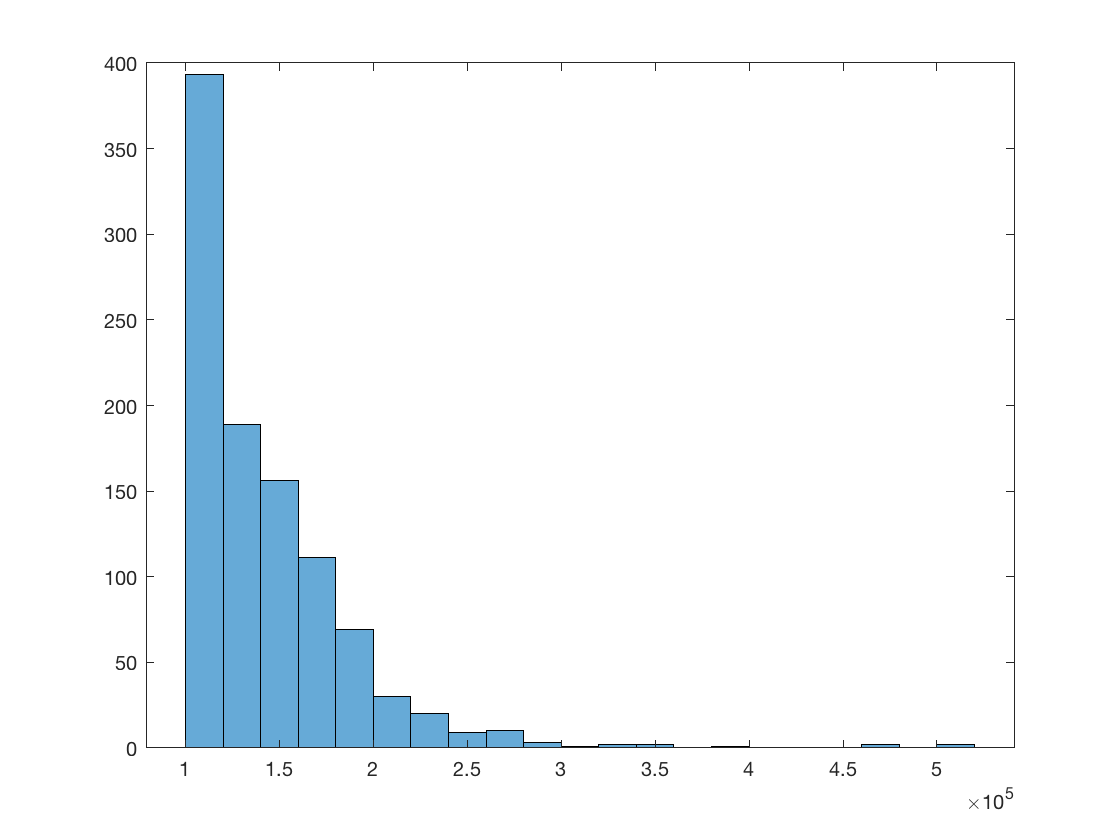

% Part 3. Shape of distribution of a sample with n = 1,000
pm = randperm(pop);
histogram(onunivcol16.Salary(pm(1:1000)));